clear all;
close all;

### Setar(2;1;1)


$$$$
X_t =
\begin{cases}
\phi_{1,0} + \phi_{1,1} X_{t-1} + \varepsilon_t, & \text{if } X_{t-1} \leq r, \\
\phi_{2,0} + \phi_{2,1} X_{t-1} + \varepsilon_t, & \text{if } X_{t-1} > r,
\end{cases}
$$$$


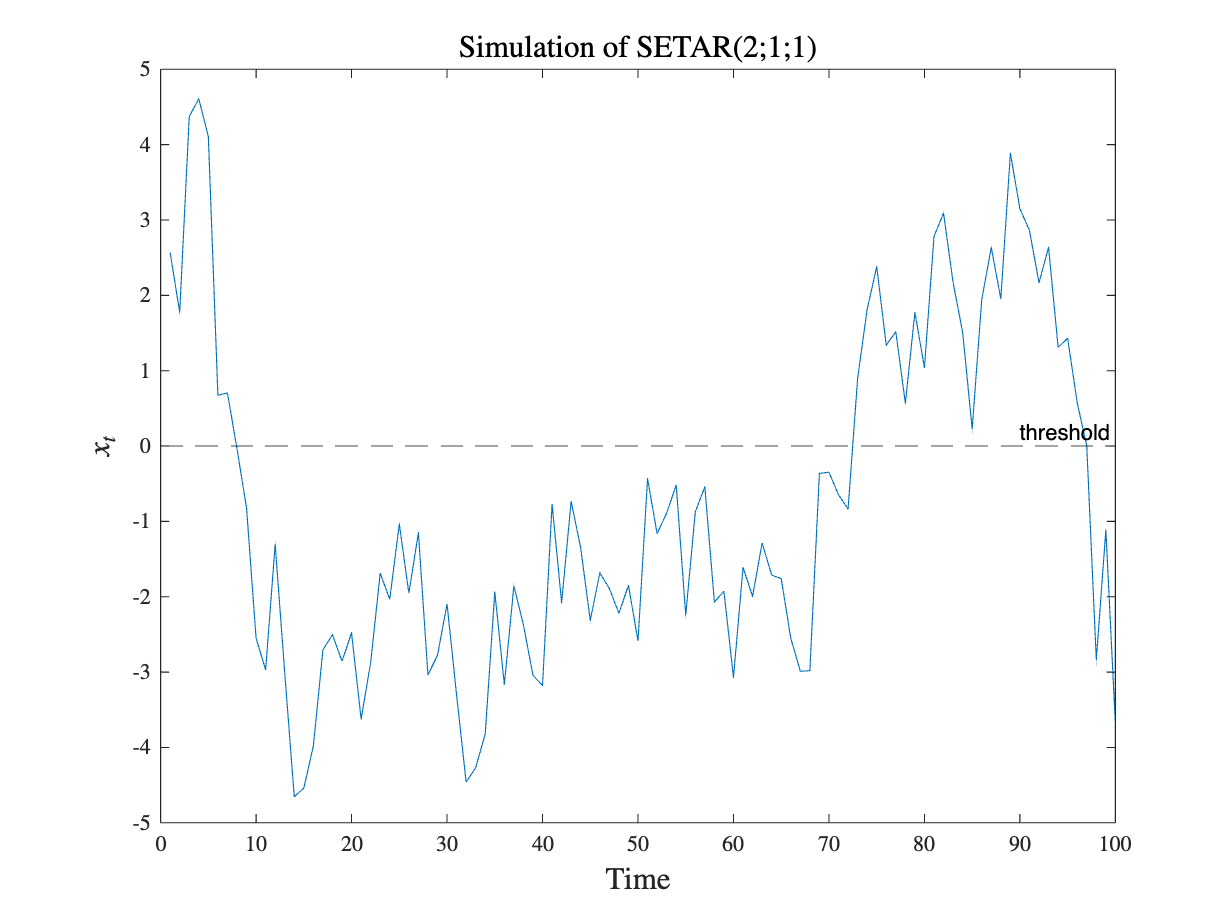

N=100;
e_k=randn(N,1);
x_k=zeros(N,1);

% Parameters
r  = 0;                  % threshold
phi10 = -1; phi11 = 0.6;  % regime 1 coefficients
phi20 = 1; phi21 = 0.4; % regime 2 coefficients

%assume first point is at x=0, decide what regime we are in to calculate
%the next point. 

if 0 <= 1
    x_k(1)=sqrt(1/(1-phi11^2))*e_k(1); 
else 
    x_k(1) = sqrt(1/(1-phi21^2))*e_k(1);
end

% Simulate
for n = 2:N
    if x_k(n-1) <= r
        % Regime 1
        x_k(n) = phi10 + phi11 * x_k(n-1) + e_k(n);
    else
        % Regime 2
        x_k(n) = phi20 + phi21 * x_k(n-1) + e_k(n);
    end
end

% Plot the simulated series
figure;
plot(x_k);
yline(r,"k--", "threshold");
xlabel('Time', 'FontSize', 14);
ylabel('$x_t$', "Interpreter","latex","FontSize",14);
title('Simulation of SETAR(2;1;1)', 'FontSize',14);

function modelLatex = setarLatex(phi10,phi11,phi20,phi21,r)
    modelLatex = sprintf(['$$\n' ...
        'X_t = \n' ...
        '\\begin{cases}\n' ...
        '%.2f + %.2f X_{t-1} + \\varepsilon_t, & \\text{if } X_{t-1} \\leq %.2f, \\\\\n' ...
        '%.2f + %.2f X_{t-1} + \\varepsilon_t, & \\text{if } X_{t-1} > %.2f\n' ...
        '\\end{cases}\n' ...
        '$$'], ...
        phi10,phi11,r,phi20,phi21,r);
end


disp(setarLatex(phi10,phi11,phi20,phi21,r));

$$
X_t = 
\begin{cases}
-1.00 + 0.60 X_{t-1} + \varepsilon_t, & \text{if } X_{t-1} \leq 0.00, \\
1.00 + 0.40 X_{t-1} + \varepsilon_t, & \text{if } X_{t-1} > 0.00
\end{cases}
$$


### IGAR(2;1)


$$\[
X_t =
\begin{cases}
a^{(1)}_0 + a^{(1)}_1 X_{t-1} + \varepsilon^{(1)}_t, & \text{if } J_t=1 \quad\text{(prob. } p_1),\\[4pt]
a^{(2)}_0 + a^{(2)}_1 X_{t-1} + \varepsilon^{(2)}_t, & \text{if } J_t=2 \quad\text{(prob. } p_2=1-p_1).
\end{cases}
\]$$


## Simulation of IGAR(2;1): i.i.d. regime switching AR(1)

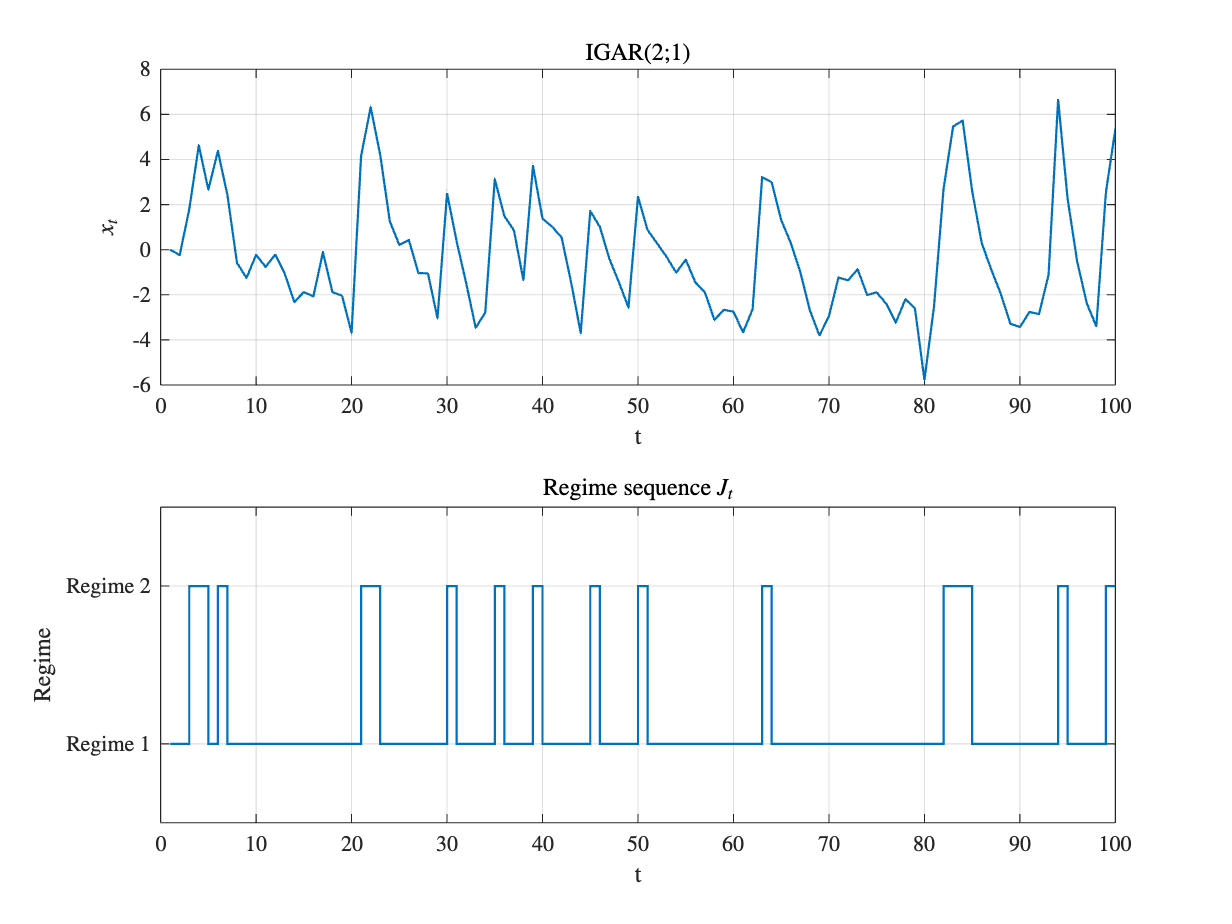


% Regime probabilities (p1 + p2 = 1)
p1  = 0.8; 
p2  = 1 - p1;

% Regime-specific AR(1) 
a0 = [-1 , 4];   % [a0^(1), a0^(2)]
a1 = [0.6, 0.4];   % [a1^(1), a1^(2)]

% Regime-specific innovation std devs (allow different noise per regime)
sigma = [1.0, 1.0]; % [sigma_1, sigma_2]

% Pre-allocate
x  = zeros(N,1);
J  = zeros(N,1);      
e1 = randn(N,1);    


% Draw i.i.d. regimes J_t
u = rand(N,1);
J(u <= p1) = 1;
J(u  > p1) = 2;

% Initial condition 
if J(1) == 1
    x_k(1)=sqrt(1/(1-a1(1)^2))*e_k(1); 
else 
    x_k(1) = sqrt(1/(1-a1(2)^2))*e_k(1);
end

% Simulate
for t = 2:N
    j = J(t);                    
    eps_t = sigma(j) * e1(t);
    x(t) = a0(j) + a1(j)*x(t-1) + eps_t;
end

% ---- Plots ----
t = (1:N)';

figure('Name','IGAR(2;1) simulation','Color','w');
subplot(2,1,1);
plot(t, x, 'LineWidth', 1);
xlabel('t'); ylabel('$x_t$', Interpreter="latex"); title('IGAR(2;1)'); grid on;

subplot(2,1,2); % visualize regimes as a binary strip
stairs(t, J, 'LineWidth', 1);
ylim([0.5 2.5]); yticks([1 2]); yticklabels({'Regime 1','Regime 2'});
xlabel('t'); ylabel('Regime'); title('Regime sequence $J_t$', Interpreter="latex"); grid on;

function modelLatex = igarLatex(a0,a1,p)
    modelLatex = sprintf(['$$\n' ...
        'X_t = a_0^{(J_t)} + a_1^{(J_t)} X_{t-1} + \\varepsilon_t^{(J_t)}, \\\\\n' ...
        'J_t \\sim \\text{i.i.d.}, \\quad \\Pr(J_t=1)=%.2f, \\; \\Pr(J_t=2)=%.2f \\\\\n' ...
        'a_0^{(1)}=%.2f,\\; a_1^{(1)}=%.2f,\\\\\n' ...
        'a_0^{(2)}=%.2f,\\; a_1^{(2)}=%.3f\n' ...
        '$$'], ...
        p(1),p(2), a0(1),a1(1), a0(2),a1(2));
end

p = [p1 p2];   % regime probabilities
disp(igarLatex(a0,a1,p));

$$
X_t = a_0^{(J_t)} + a_1^{(J_t)} X_{t-1} + \varepsilon_t^{(J_t)}, \\
J_t \sim \text{i.i.d.}, \quad \Pr(J_t=1)=0.80, \; \Pr(J_t=2)=0.20 \\
a_0^{(1)}=-1.00,\; a_1^{(1)}=0.60,\\
a_0^{(2)}=4.00,\; a_1^{(2)}=0.400
$$


### MMAR(2;1)

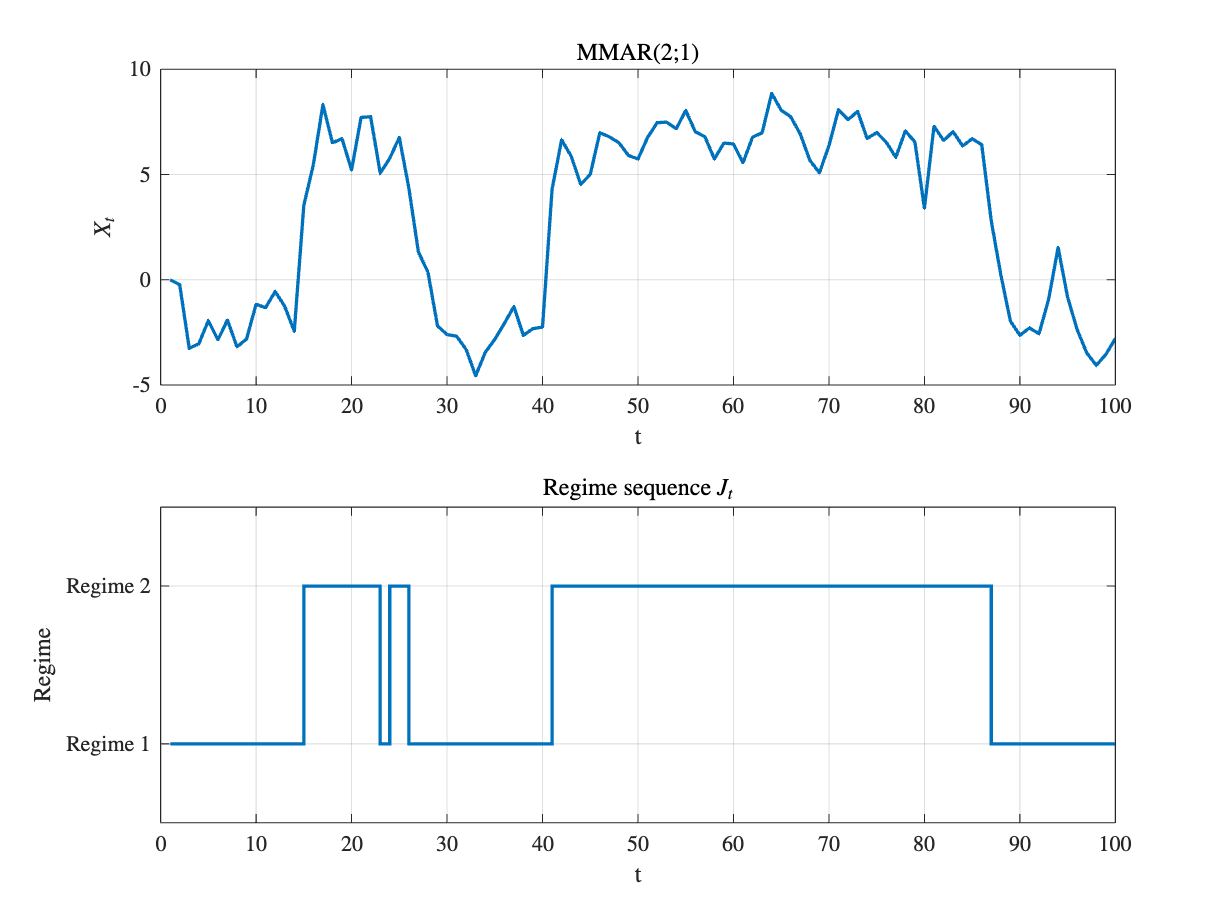

P=[0.9, 0.1;
   0.1, 0.9];

J  = zeros(N,1);     
J(1)=1;  
u = rand(N,1);

for t=2:N; 
    if(J(t-1)==1)
        if(u(t)<=P(1,1))
            J(t)=1;
        else 
            J(t)=2;
        end
    else
        if(u(t)<=P(2,2))
            J(t)=2;
        else
            J(t)=1;
        end
    end
    j = J(t);                    
    eps_t = sigma(j) * e1(t);
    x(t) = a0(j) + a1(j)*x(t-1) + eps_t;
end


% ---- Plots ----
t = (1:N)';

figure('Name','MMAR(2;1) simulation','Color','w');
subplot(2,1,1);
plot(t, x, 'LineWidth', 1.5);
xlabel('t'); 
ylabel('$X_t$', "Interpreter","latex"); 
title('MMAR(2;1)', "Interpreter","latex"); 
grid on;

subplot(2,1,2); % visualize regimes as a binary strip
stairs(t, J, 'LineWidth', 1.5);
ylim([0.5 2.5]); 
yticks([1 2]); 
yticklabels({'Regime 1','Regime 2'});
xlabel('t'); 
ylabel('Regime', "Interpreter","latex"); 
title('Regime sequence $J_t$', "Interpreter","latex"); 
grid on;

function modelLatex = mmarLatex(a0,a1,P)
    modelLatex = sprintf(['$$\n' ...
        'X_t = a_0^{(J_t)} + a_1^{(J_t)} X_{t-1} + \\varepsilon_t^{(J_t)}, \\\\\n' ...
        'J_t \\sim \\text{Markov chain with transition matrix } P = \n' ...
        '\\begin{bmatrix}\n' ...
        '%.2f & %.2f \\\\\n' ...
        '%.2f & %.2f \n' ...
        '\\end{bmatrix}, \\\\\n' ...
        'a_0^{(1)}=%.2f,\\; a_1^{(1)}=%.3f,\\\\\n' ...
        'a_0^{(2)}=%.2f,\\; a_1^{(2)}=%.3f\n' ...
        '$$'], ...
        P(1,1),P(1,2),P(2,1),P(2,2), a0(1),a1(1), a0(2),a1(2));
end

disp(mmarLatex(a0,a1,P));

$$
X_t = a_0^{(J_t)} + a_1^{(J_t)} X_{t-1} + \varepsilon_t^{(J_t)}, \\
J_t \sim \text{Markov chain with transition matrix } P = 
\begin{bmatrix}
0.90 & 0.10 \\
0.10 & 0.90 
\end{bmatrix}, \\
a_0^{(1)}=-1.00,\; a_1^{(1)}=0.600,\\
a_0^{(2)}=4.00,\; a_1^{(2)}=0.400
$$
